## [Proportional Integral (PI) Control](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralControl)

A variation of Proportional Integral Derivative (PID) control is to use only the proportional and integral terms as PI control. The PI controller is the most popular variation, even more than full PID controllers. The value of the controller output u(t) is fed into the system as the manipulated variable input.


$$e(t) = SP-PV$$



$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t e(t)dt$$


The $u_{bias}$ term is a constant that is typically set to the value of $u(t)$ when the controller is first switched from manual to automatic mode. This gives "bumpless" transfer if the error is zero when the controller is turned on. The two tuning values for a PI controller are the controller gain, $K_c$ and the integral time constant $\tau_I$. The value of $K_c$ is a multiplier on the proportional error and integral term and a higher value makes the controller more aggressive at responding to errors away from the set point. The set point (*SP*) is the target value and process variable (*PV*) is the measured value that may deviate from the desired value. The error from the set point is the difference between the *SP* and *PV* and is defined as $e(t) = SP - PV$.

## Discrete PI Controller

Digital controllers are implemented with discrete sampling periods and a discrete form of the PI equation is needed to approximate the integral of the error. This modification replaces the continuous form of the integral with a summation of the error and uses $\Delta t$ as the time between sampling instances and $n_t$ as the number of sampling instances.


$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\sum_{i=1}^{n_t} e_i(t)\Delta t$$


## Overview of PI Control

PI control is needed for non-integrating processes, meaning any process that eventually returns to the same output given the same set of inputs and disturbances. A P-only controller is best suited to integrating processes. Integral action is used to remove offset and can be thought of as an adjustable $u_{bias}$.

Common tuning correlations for PI control are the ITAE (Integral of Time-weighted Absolute Error) method and IMC (Internal Model Control). IMC is an extension of *lambda* tuning by accounting for time delay. The parameters $K_c$, $\tau_p$, and $\theta_p$ are obtained by fitting dynamic input and output data to a first-order plus dead-time (FOPDT) model (see L6 and L7).

## [] Lecture video here

## IMC Tuning Correlations

Each process has different characteristics and requirements. The same unit operation at different locations within the same plant can have different control characterstics due to climate, construction, and other variances. In addition, different processes have different objectives: the temperature controller of an oven may seek to achieve the target temperature as fast as possible while the controller for a flowmeter may seek to avoid oscillation and chattering. **Tuning Correlations** provide rough guidance for PID tuning parameters. After using a tuning correlation, the parameters should be further tuned with the specific objective in mind to balance how agressive the response is, and resulting oscillation. This delicate process of adjusting is similar to *tuning* an instrument where fine adjustments are made to achieve the desired pitch.


$$\mathrm{Aggressive\,Tuning:} \quad \tau_c = \max \left( 0.1 \tau_p, 0.8 \theta_p \right)$$



$$\mathrm{Moderate\,Tuning:} \quad \tau_c = \max \left( 1.0 \tau_p, 8.0 \theta_p \right)$$



$$\mathrm{Conservative\,Tuning:} \quad \tau_c = \max \left( 10.0 \tau_p, 80.0 \theta_p \right)$$



$$K_c = \frac{1}{K_p}\frac{\tau_p}{\left( \theta_p + \tau_c \right)} \quad \quad \tau_I = \tau_p$$


Note that with moderate tuning and negligible dead-time $(\theta_p \rightarrow 0  \text{  and }  \tau_c = 1.0 \tau_p)$, IMC reduces to simple tuning correlations that are easy to recall without a reference book.


$$K_c = \frac{1}{K_p} \quad \quad \tau_I = \tau_p \quad \quad \mathrm{Simple\,tuning\,correlations}$$


## ITAE Tuning Correlations

Different tuning correlations are provided for disturbance rejection (also referred to as *regulatory* control) and set point tracking (also referred to as *servo* control).


$$K_c = \frac{0.586}{K_p}\left(\frac{\theta_p}{\tau_p}\right)^{-0.916} \quad \tau_I = \frac{\tau_p}{1.03-0.165\left(\theta_p/\tau_p\right)}\quad\mathrm{Set\;point\;tracking}$$



$$K_c = \frac{0.859}{K_p}\left(\frac{\theta_p}{\tau_p}\right)^{-0.977} \quad \tau_I = \frac{\tau_p}{0.674}\left(\frac{\theta_p}{\tau_p}\right)^{0.680}\quad\mathrm{Disturbance\;rejection}$$


## Anti-Reset Windup

An important feature of a controller with an integral term is to consider the case where the controller output u(t) saturates at an upper or lower bound for an extended period of time. This causes the integral term to accumulate to a large summation that causes the controller to stay at the saturation limit until the integral summation is reduced. Anti-reset windup is that the integral term does not accumulate if the controller output is saturated at an upper or lower limit.

Suppose that a driver of a vehicle set the desired speed set point to a value higher than the maximum speed. The automatic controller would saturate at full throttle and stay there until the driver lowered the set point. Suppose that the driver kept the speed set point higher than the maximum velocity of the vehicle for an hour. The discrepancy between the set point and the current speed would create a large integral term. If the driver then set the speed set point to zero, the controller would wait to lower the throttle until the negative error cancels out the positive error from the hour of driving. The automobile would not slow down but continue at full throttle for an extended period of time. This undesirable behavior is fixed by implementing anti-reset windup.

## Exercise

The purpose of this exercise is to investigate the cause of offset in a P-only controller and oscillations in a PI controller.

Consider a first order plus dead time process as $\tau_p \frac{dy}{dt} = -y + K_p u \left(t-\theta_p\right)$with $K_p = 2$, $\tau_p = 200$, and $\theta_p = 0$. 

Kp = 2;      % Process Gain
tauP = 2;    % Process Time Constant
thetaP = 0;  % Process Dead Time

**Open Loop Response**

Below, a control input is manually changed from 0 to 10 and back again. The functions `FOPDT` and `openLoopSim `included below may be helpful. Before running this section predict wether the response will be smooth or have oscillations. Then, explain afterword why the response either had oscillations or was smooth.

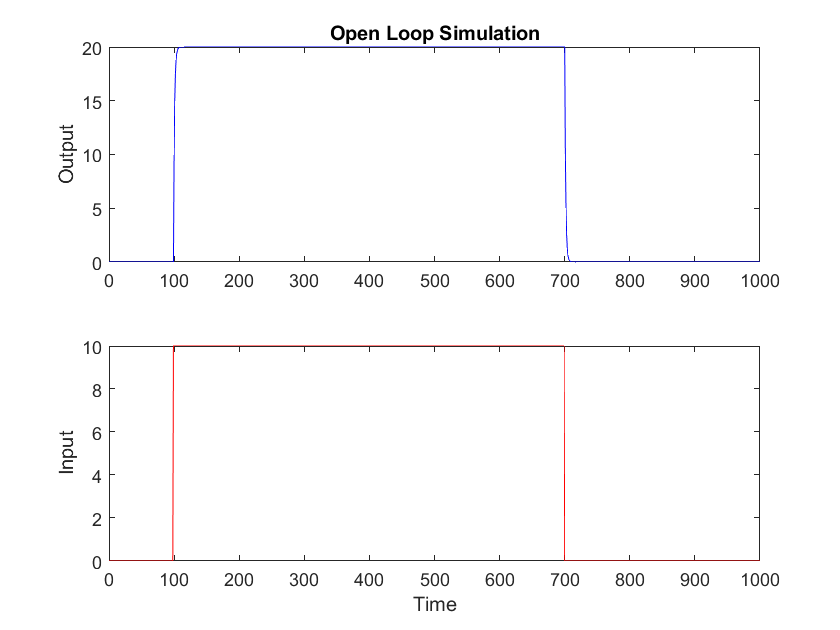

% a
t = linspace(0, 1000, 1001);
u = zeros(1, 1001);
u(100:700) = 10;

y_openLoop = openLoopSim(t, u, Kp, tauP, thetaP);

**P-only Control**

Simulate the behavior for using a P-only controller with $K_c = 2$ and $K_c=0.5$. Implement a set point change from 0 to 10 and back in automatic mode (closed-loop). Include a plot of the error between the set point (*SP*) and process variable (*PV*). What happens with increased $K_c$ in terms of offset and oscillation?

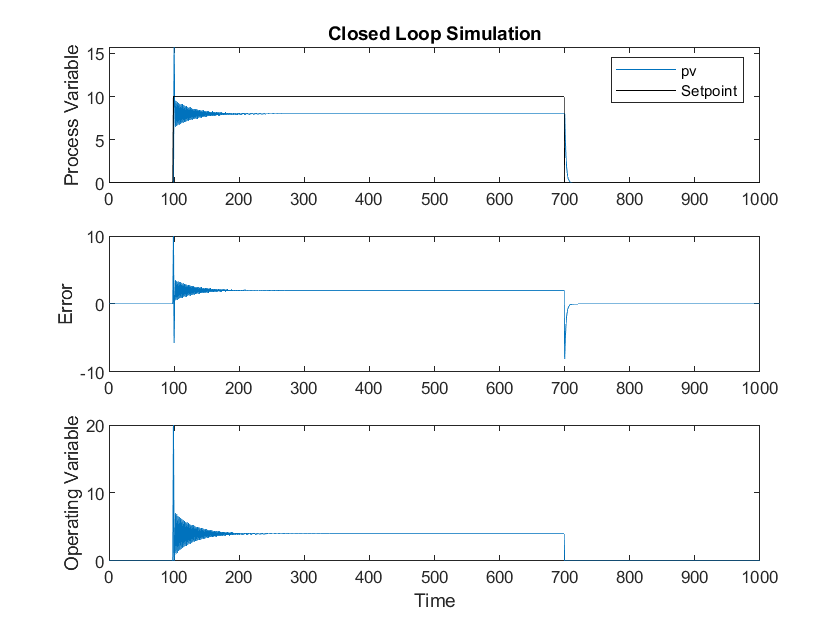

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Kc = 2;
sp = zeros(1001);
sp(100:700) = 10;
pid_ = [Kc 0 0];
process_ = [Kp tauP thetaP];
closedLoopSim(t, sp, process_, pid_)


Kc = 0.5

Kc = 0.5000

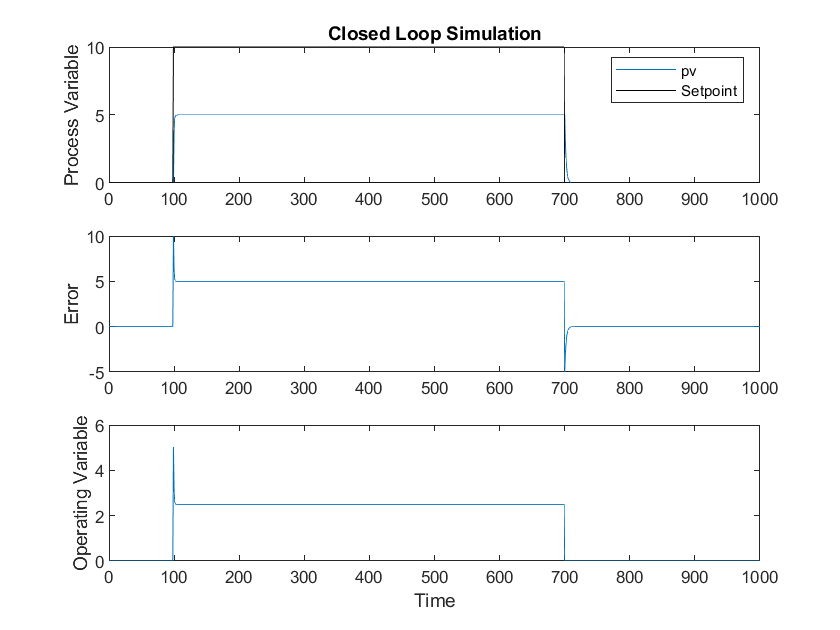

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


pid_ = [Kc 0 0];
closedLoopSim(t, sp, process_, pid_)

**PI Control**

Integral reset time: 200


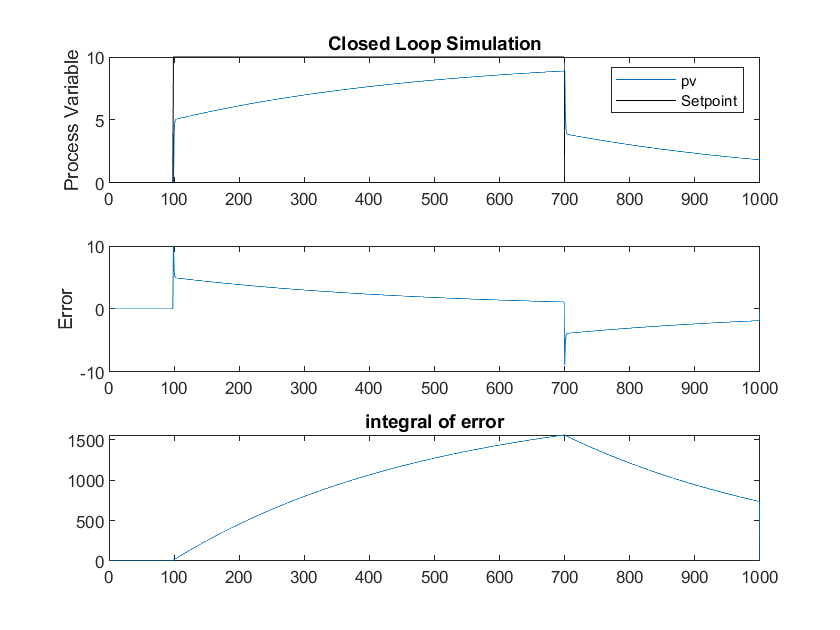

Integral reset time: 100


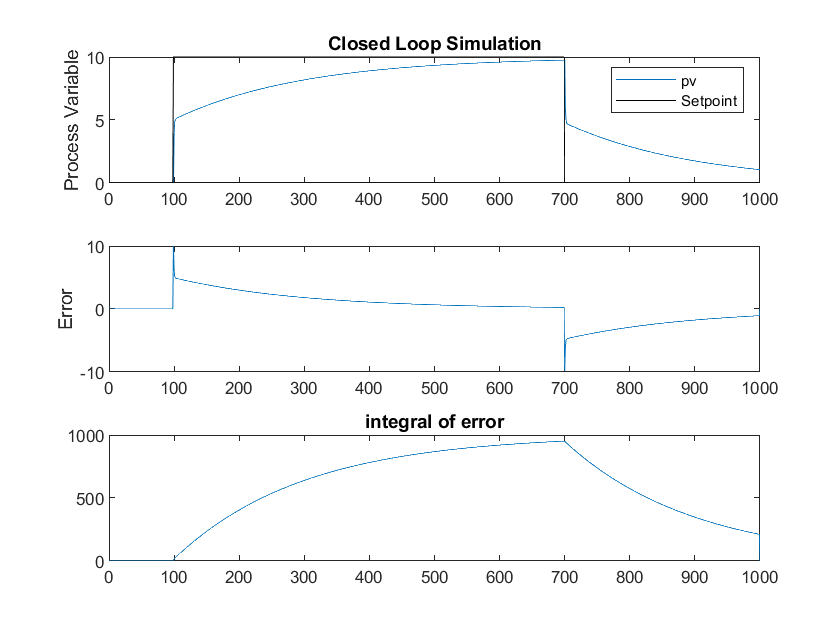

Integral reset time: 10


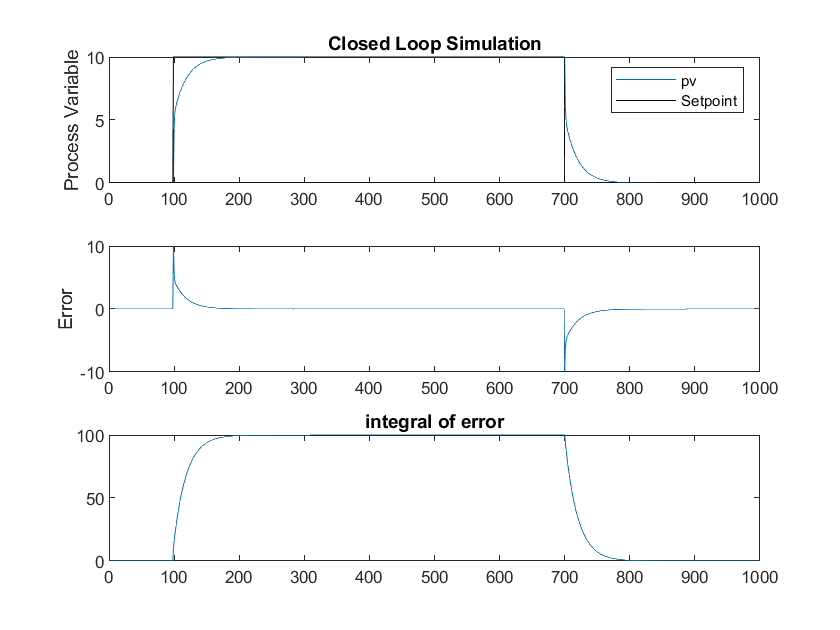

viewSolutionPI(false)

Configure the controller to add an integral term in addition to the proportional control with $K_c = 2$. Simulate the PI controller response with integral reset times $\tau_I=200, 100, 10$. Include a plot of the integral of the error between the set point (*SP*) and process variable (*PV*) with anti-reset windup. Explain what happens and why.

**Open Loop Response with Dead Time**

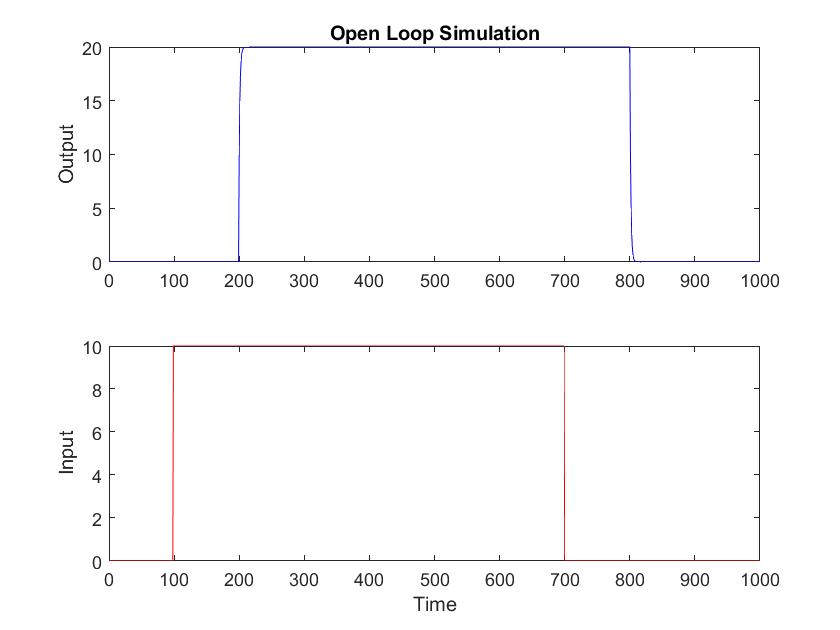

viewSolutionPI2(false)

Add dead time $\theta_p=100$ as an input delay. Simulate the behavior for making a step change in manual mode from 0 to 10 (and back). Explain what happens in terms of oscillations.

**P-only Control with Dead Time**

Controller gain: 2


process_ =      2     2   100


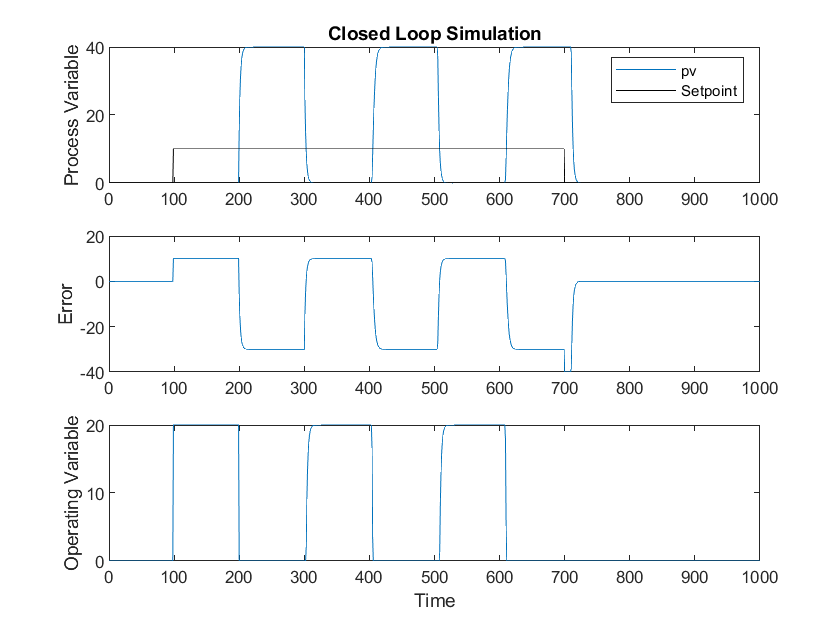

Controller gain: 0.5


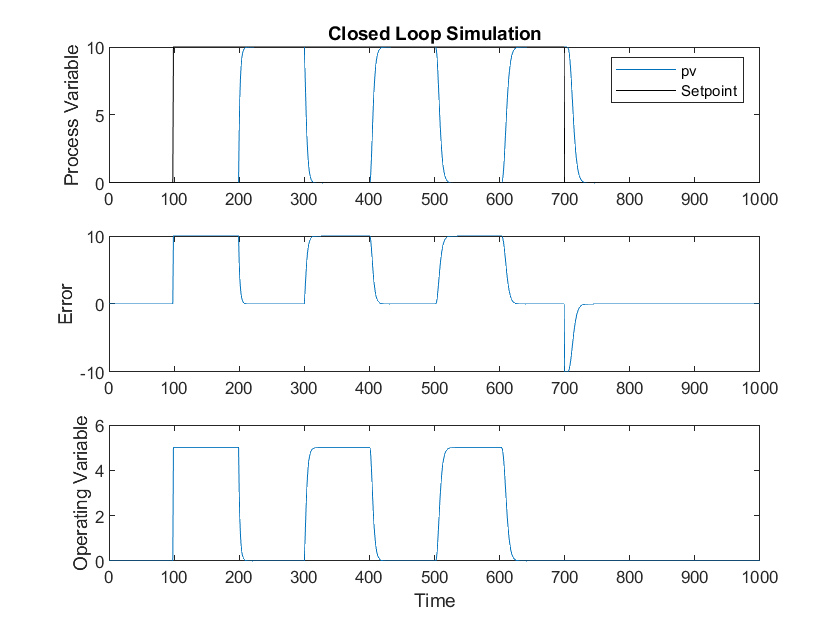

viewSolution3(false)

With the dead time, simulate the response of a P-only controller with $K_c=2$ and $K_c=0.5$. Implement a set point change from 0 to 10 and back in automatic mode (closed-loop). Include a plot of the error between the set point (*SP*) and process variable (*PV*). What happens with increased $K_c$ in terms of offset and oscillation?

**PI Control with Dead Time**

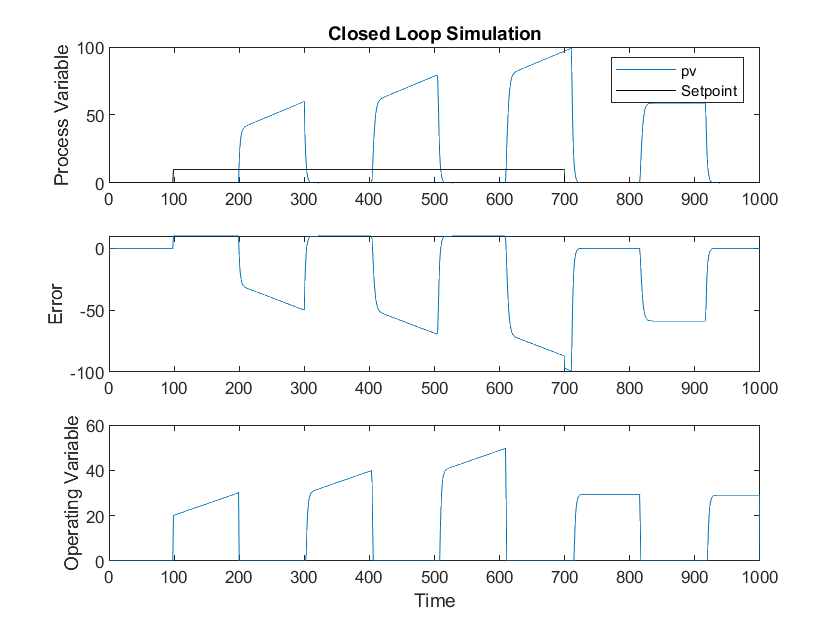

viewSolution4  (false)

Simulate the response of a PI controller with $\tau_I=200$. Include a plot of the integral of the error between the set point (*SP*) and process variable (*PV*) with anti-reset windup. Explain what happens and why. Explain the results.

**Summary Questions**

- Based on the observations in manual mode, is the process stable or unstable?

- Why does P-only control have persistent offset?

- What is the effect of dead time on P-only and PI control?

- If the process is stable, why can the control system make it unstable?

function dydt = FOPDT(t,y,u,Kp,tauP)
    % Returns the derivative of an FOPDT Equation
    % INPUTS
    % t: Time (unused)
    % y: Output (assumed that the steady state condition is 0)
    % u: Input (assumed that the steady state condition is 0)
    % Kp: Process Gain (dimensionless)
    % tauP: Process Time Constant (same units as time)
    % OUTPUT
    % dydt: change in output per time
    
    dydt = -y/tauP + Kp/tauP*u;
end

function y_ = openLoopSim(t_, u_, Kp, tauP, thetaP)
    % Simulates an open loop FOPDT Process
    % INPUTS
    % t_(array): Time array
    % u_(array): Input array(assumed that the steady state condition is 0)
    % Kp: Process Gain (dimensionless)
    % tauP: Process Time Constant (same units as time)
    % thetaP: Process Dead Time
    % OUTPUT
    % y_(array): output array
    
    y_ = zeros(1,length(t_)); % Create Output array
    
    for i=1:length(t_)-1
        % offset deadtime by interpolating
        if (t_(i)-thetaP) <= 0
            ui = u_(1);
        else
            ui = interp1(t_, u_, t_(i)-thetaP);
        end
        
        % simulate output change with ode45
        tspan = [t_(i), t_(i+1)];
        [~,y] = ode45(@(y,t)FOPDT(t_(i),y_(i),ui,Kp,tauP), tspan, y_(i));
        y_(i+1) = y(end);
    end
    
    % graph results
    figure()
    subplot(2, 1, 1)
    plot(t_, y_, 'b-')
    title('Open Loop Simulation')
    ylabel('Output')
    subplot(2, 1, 2)
    plot(t_, u_, 'r-')
    ylabel('Input')
    xlabel('Time') 
end

function [pv_, op_, e_, ie_] = closedLoopSim(t_, sp_, process_constants, controller_constants)
    % Simulates a P, PI, or PID Controller. Include the constants in
    % controller_constants for the portions of the controller desired. 0 is
    % thye steady state value for both the input and output.
    
    % INPUTS
    % t_(array): Time array
    % sp_(array): Setpoint array (should be the same size as t_)
    % process_constants(array): constants that determine the FOPDT process
    %     [kP tauP thetaP]
    %     kP: Process Gain (unitless)
    %     tauP: Process Time Constant (same time units as time array)
    %     thetaP: Process Dead Time
    % controller_constants(array): constants for PID Equation
    %     [kC tauI tauD]
    %     kC: Controller Gain (controller/error)
    %     tauI: Integral Time Constant
    %     tauD: Derivative Time Constant
    %     
    % OUTPUT
    % pv_: process value (output)(0 assumed as steady state value for input
    % and output)
    % op_: operating point (controlled value for each time point)
    % e_: error vector error at any given time
    % ie_: integral of error at any given time
    
    % unpack arrays
    %% Process Constants
    kP = process_constants(1);
    tauP = process_constants(2);
    thetaP = process_constants(3);
    %% PID Tuning Constants
    kC = controller_constants(1);
    tauI = controller_constants(2);
    tauD = controller_constants(3);
    
    % specify number of steps
    ns = length(t_);
    delta_t = t_(2)-t_(1);

    % storage for recording values
    op_  = zeros(1, ns);    % controller output
    pv_  = zeros(1, ns);    % process variable
    e_   = zeros(1, ns);    % error
    ie_  = zeros(1, ns);    % integral of the error
    dpv_ = zeros(1, ns);    % derivative of the pv
    P_   = zeros(1, ns);    % proportional
    I_   = zeros(1, ns);    % integral
    D_   = zeros(1, ns);    % derivative

    % Upper and Lower limits on OP
    op_hi = 100.0;
    op_lo = 0.0;

    % loop through time steps    
    for i = 1:ns-1 %Just do a:ns not 1:ns+1
        e_(i) = sp_(i) - pv_(i);   
        if i > 1  % calculate starting on second cycle
            dpv_(i) = (pv_(i)-pv_(i-1))/delta_t;
            ie_(i) = ie_(i-1) + e_(i) * delta_t;
        end
        
        % PID Equation
        P_(i) = kC * e_(i);
        if tauI  % integral control if constant is not 0
            I_(i) = kC/tauI * ie_(i);
        end
        if tauD  % derivative control if constant is not 0
            D_(i) = - kC * tauD * dpv_(i);
        end
        op_(i) = P_(i) + I_(i) + D_(i);
        
        % Anti-reset windup
        if op_(i) > op_hi  % check upper limit
            op_(i) = op_hi;
            ie_(i) = ie_(i) - e_(i) * delta_t; % anti-reset windup
        end
        if op_(i) < op_lo  % check lower limit
            op_(i) = op_lo;
            ie_(i) = ie_(i) - e_(i) * delta_t; % anti-reset windup
        end
        
        % Implement time delay
        if t_(i)-thetaP < 0
            iop = op_(1);
        else
            iop = interp1(t_, op_, t_(i)-thetaP);
        end
        
        % Simulate process
        ts = [delta_t*(i-1),delta_t*i];
        [~, y] = ode45(@(t, y) FOPDT(t,y,iop,kP,tauP),ts, pv_(i));
        pv_(i+1) = y(end);

    end
    % Plot
    figure()
    subplot(3,1,1)
    plot(t_, pv_)
    hold on
    plot(t_, sp_, 'k-')
    legend({'pv' 'Setpoint'})
    ylabel('Process Variable')
    title('Closed Loop Simulation')
    subplot(3,1,2)
    plot(t_, e_)
    ylabel('Error')
    subplot(3,1,3)
    plot(t_, op_)
    ylabel('Operating Variable')
    xlabel('Time') 
end

Solutions

function viewSolutionPI(view)
if view
	disp("disp('Integral reset time: 200')" + newline + ...
	     "pid_ = [Kc 200 0];" + newline + ...
	     "[~, ~, ~, ie] = closedLoopSim(t, sp, process_, pid_);" + newline + ...
	     "plot(t, ie)" + newline + ...
	     "title('integral of error')" + newline + ...
	     "" + newline + ...
	     "disp('Integral reset time: 100')" + newline + ...
	     "pid_ = [Kc 100 0];" + newline + ...
	     "[~, ~, ~, ie] = closedLoopSim(t, sp, process_, pid_);" + newline + ...
	     "plot(t, ie)" + newline + ...
	     "title('integral of error')" + newline + ...
	     "" + newline + ...
	     "disp('Integral reset time: 10')" + newline + ...
	     "pid_ = [Kc 10 0];" + newline + ...
	     "[~, ~, ~, ie] = closedLoopSim(t, sp, process_, pid_);" + newline + ...
	     "plot(t, ie)" + newline + ...
	 "end")
end
end

function viewSolutionPI2(view)
if view
	disp("y_openLoop = openLoopSim(t, u, Kp, tauP, 100);")
end
end

function viewSolution3(view)
if view
	disp("disp('Controller gain: 2')" + newline + ...
	     "pid_ = [2 0 0];" + newline + ...
	     "process_ = [Kp tauP 100];" + newline + ...
	     "closedLoopSim(t, sp, process_, pid_);" + newline + ...
	     "" + newline + ...
	     "disp('Controller gain: 0.5')" + newline + ...
	     "pid_ = [0.5 0 0];" + newline + ...
	 "end")
end
end


function viewSolution4(view)
if view
	disp("pid_ = [2 200 0];" + newline + ...
	 "end")
end
end
